# Build a Refrigeration Model with Simscape Fluids

[⇦ Overview](matlab: OpenOverview) 

In this tutorial we will create a closed-loop refrigeration system with the goal of keeping a thermal mass within a certain temperature range for a prescribed heat load. An example of such a system is a battery chiller cold plate. A schematic for this system is shown in Figure 1. This system is composed of four primary components which convey a working fluid (refrigerant), and with it, heat from the cold plate to the environment.

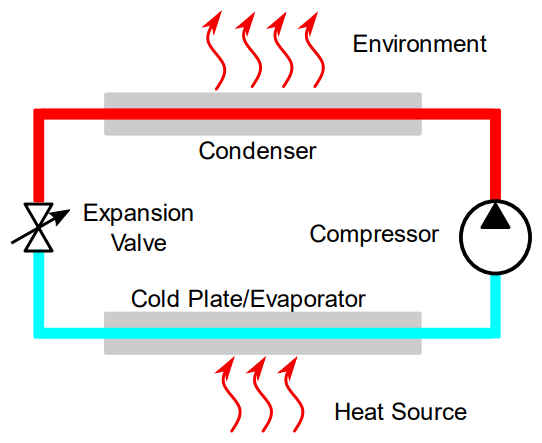

Figure 1: System model overview. The cold plate, which is heated externally is in thermal contact with a refrigeration loop, which expels its heat to the environment. The refrigeration loop contains four main components, an evaporator, a condenser a compressor and an expansion valve.

## System Components Overview

The **compressor** heats the cold, evaporated fluid, pressurizes and transports it to the condenser side where the fluid can give up its heat to the environment. The refrigerant enters and leaves the compressor as super-heated vapor. The compressor we will model will be capable of running at different speeds and will have a flow rate that depends on the operating speed and the pressure ratio between the condenser and evaporator. Our compressor will be regulated by a PI controller which responds to the cold plate temperature.

The **condenser** is a device that allows the high-pressure refrigerant to phase change to liquid by exchanging heat to another cooler stream. The refrigerant enters the condenser as a super-heated vapor and exits as a sub-cooled liquid. Like an evaporator, this device consists of two working fluid channels separated by a thin conductive wall. In this case, the fluid will exchange heat with a moist air stream, which has a constant entrance temperature, humidity, and flow rate.

The **expansion valve** regulates the mass flow and pressure difference between the condenser and evaporator. Expansion valves can either be of the Thermal Expansion type (TXV) or Electronic Expansion type (EEV) The refrigerant enters the valve as a sub-cooled liquid and exits in a vapor-liquid equilibrium state. The expansion valve opening is typically controlled to maintain a slightly super-heated vapor at the evaporator exit. Our valve (EEV type) will accomplish this by measuring the evaporator exit state and use the value to adjust a PI controller which sets the valve’s cross-sectional area.

The **evaporator** is a device which conveys heat to a refrigerant at low temperature, pressure, and quality to vaporize it. The refrigerant typically enters the evaporator in a vapor-liquid equilibrium state and leaves it as a super-heated vapor. Often the evaporator consists of two isolated working fluid channels in thermal contact via a highly conductive wall. Here, however, we will represent the other “side” of the evaporator as the cold plate connected to a 1 kW heat load.

The **cold plate** for this example is tied to a heat source, which we will model as a boundary condition. Since we will just be setting the value mathematically, we don't need to worry about the physical details of where the heat is coming from. In a larger scale model, the heat would likely come from another fluid like ethylene glycol or oil circulating through the heat generating devices. In our model, the cold plate will be represented by a 10 kg thermal mass made from aluminum.

### Simulation Goal

Our specific objective is to build a refrigeration system which can maintain a 10 kg aluminum cold plate at 5$^{\circ}$C. This cold plate will be attached to a heat source with a nominal value of 1 kW. The system needs to be able to operate between environmental temperatures of 15$^{\circ}$C and 40$^{\circ}$C.

## The Working Fluid

The first step in the process of modeling a refrigeration system is to choose the working fluid. This choice depends on many factors, including the expected operating range, cost, and environmental considerations. In this example, we will use R-1234yf for the refrigerant, which is commonly used in automotive applications for systems within our range of temperatures. The pressure enthalpy diagram for this fluid is shown in Figure 2. From this diagram we can see the refrigerant has vapor-liquid states for temperatures above our maximum expected environmental temperature of 40$^{\circ}$C (315.15 K), which will allow the condenser to operate properly below its critical point.

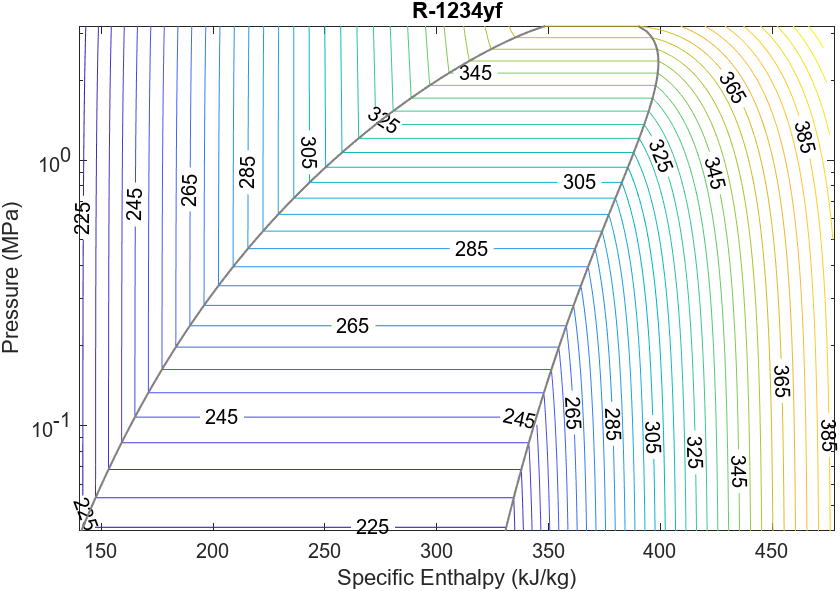

Figure 2: Pressure-enthalpy diagram for the R-1234yf working fluid.

To simulate a fluid network, it is necessary to provide Simscape with the properties for the fluid to be used. For a refrigerant these properties include the temperature/pressure phase coexistence curve, the specific energy, specific enthalpy, specific volume, viscosity, etc. These properties must be provided in the liquid, vapor, and vapor-liquid coexistence regions as they determine the flow and heat transfer of the fluid according to the local thermodynamic state. For two-phase systems in Simscape we use a mean-field model for all thermodynamic computations with pressure and specific internal energy as the state variables. All other properties are computed by interpolation on the tables provided.

  **Try**. 

- Open Simscape

ssc_new

        2. Double-click in the Simulink window 

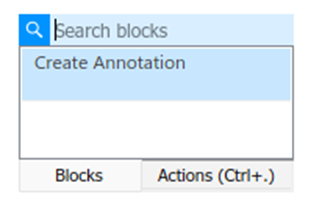

and type: "Two-Phase Fluid Predefined Properties (2P)" in the search bar.

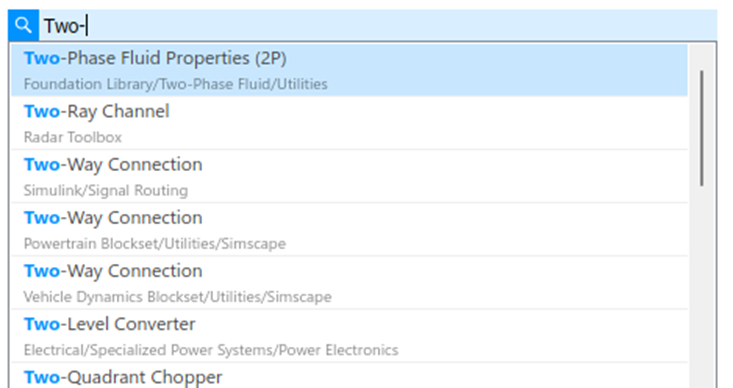 

Once you have located the appropriate block in the Foundation Library/Two-Phase Fluid/Utilities, select it. 

        3. Double-click the block to open its properties table. There are a variety of standard fluids included as options. Select "R-1234yf" from the drop-down.

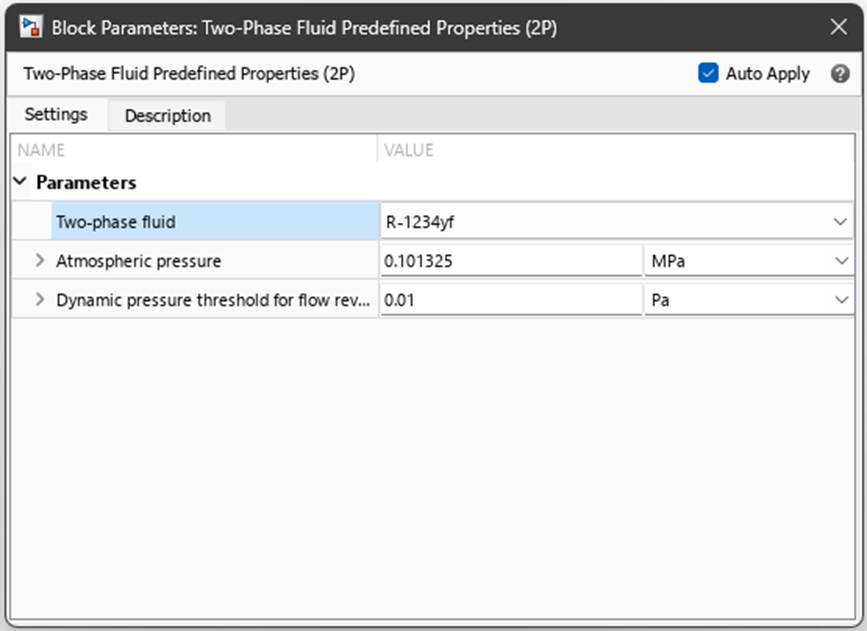

## Modeling the Cold Plate and Evaporator

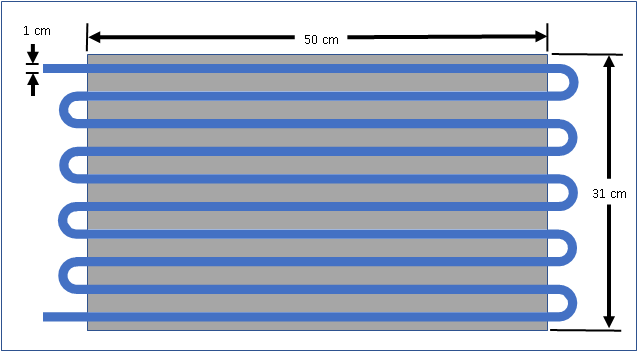

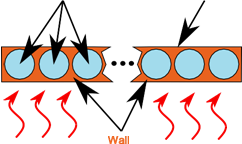

Figure 3: Cold plate cut-away. The cold plate consists of a 50 cm x 31 cm x 2.4 cm aluminum block with 1 cm diameter channels bored through it. These channels are connected in a serpentine path with brazed copper tubing. The total tube length is approximately 5 m. The refrigerant enters one end in a vapor-liquid equilibrium state and leaves the other as super-heated vapor. On the bottom is a cutaway of the cold plate looking down the refrigerant tubes. 

To determine whether our cold plate/evaporator assembly has a 1 kW capacity we will use the geometry information provided in Figure 3 to create and parameterize a test harness model. 

  **Try**. Build the cold plate/evaporator assembly by adding the following blocks to your model.

% This data file contains the named parameter values for the evaporator
% model
evaporatorParams

1.** 3-Zone Pipe (2P) **block (**Simscape **$\bf{\rightarrow}$** Fluids**$\bf{\rightarrow}$**Two-Phase****Fluid**$\bf{\rightarrow}$**Pipes & Fittings)**

Name: Evaporator

Parameter Settings: 

- Geometry$\bf{\rightarrow}$Pipe length                                Value: `l_evap`         Units: m

- Geometry$\bf{\rightarrow}$Cross-sectional area                 Value: `a_evap  `     **Units: cm^2**

- Geometry$\bf{\rightarrow}$Hydraulic diameter                    Value: `d_evap`         **Units: cm**

- Heat Transfer$\bf{\rightarrow}$External environment heat transfer coefficient    **Value: inf**

- Heat Transfer$\bf{\rightarrow}$Wall thickness                     Value: `t_wall`         **Units: mm**

- Heat Transfer$\bf{\rightarrow}$Wall thermal conductivity    Value: `k_plate`       Units: W/m/K

- Heat Transfer$\bf{\rightarrow}$Wall specific heat                Value: `cp_plate`     Units: J/kg/K

- Heat Transfer$\bf{\rightarrow}$Wall density                         Value: `rho_plate`   **Units: g/cm^3**

2. **Thermal Mass **block to represent the aluminum plate (**Simscape**$\bf{\rightarrow}$**Foundation Library**$\bf{\rightarrow}$**Thermal**$\bf{\rightarrow}$**Elements**) 

Name: Cold Plate

Parameter Settings:

- Mass                      Value: `m_plate`     Units: kg 

- Specific heat          Value: `cp_plate`   Units: J/kg/K

3. **Conductive Heat Transfer **block to represent the conduction from the plate (**Simscape**$\bf{\rightarrow}$**Foundation Library**$\bf{\rightarrow}$**Thermal**$\bf{\rightarrow}$**Elements**) with 

Name: Wall

Parameter Settings:

- Area                               Value: `a_plate`     **Units: cm^2** 

- Thermal conductivity      Value: `k_plate`     Units: W/m/K.

4. **Heat Flow Rate Source **block to represent the heat load (**Simscape**$\bf{\rightarrow}$**Foundation Library**$\bf{\rightarrow}$**Thermal**$\bf{\rightarrow}$**Sources**) 

Name: Heat Load

Parameter Settings: 

- Heat flow rate               Value: `heat_load`     **Units: kW**

When you are done, the layout for the model should be as shown in Figure 4. Note we have set the external heat transfer coefficient for the evaporator pipe to be infinity because the refrigerant is in direct contact with the cold plate.

5. **Thermal Reference** block to give a reference point to absolute zero. (**Simscape**$\bf{\rightarrow}$**Foundation Library**$\bf{\rightarrow}$**Thermal**$\bf{\rightarrow}$**Elements**)

    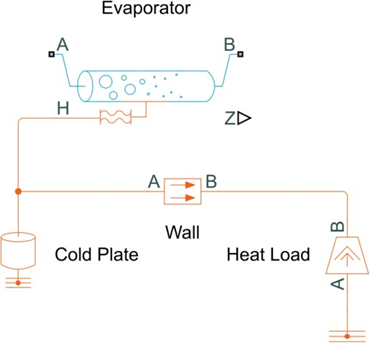

Figure 4: Evaporator/cold plate model with attached heat load. The refridgerant tubes are represented by the Evaporator block. The Cold Plate thermal mass represents the metal of the cold plate, and the Wall block represents the conduction of the heat from the Heat Load through the plate.

**Note 1:** The block elements from the thermal library are red while the block elements from the fluids library are blue. This color-coding by type can help us keep track of how particular physical elements flow through our system. 

### Testing our system

Once we have the blocks assembled for the cold plate, we need to provide boundary conditions, initial conditions, and a flow rate to ensure the heat exchange is 1 kW in the worst-case scenario, i.e., when the environmental temperature is 40$^{\circ}$C.

We need to access additional information from a reference database (e.g. thermodynamic tables, REFPROP or CoolProp) to determine the initial and boundary conditions by making some static assumptions. 

**Assumption:** The condensing temperature is 55C, sufficiently high to expel enough heat to the environment.

kelvinCelsiusShift = 273.15      % +: C -> K  and -: K -> C
Tcond = 55 + kelvinCelsiusShift  % K

load R1234yfData Pcond
Pcond = Pcond/1e3                % kPa

**Assumption:** The condenser output is 8C subcooled.

Tsc = Tcond - 8;                 % K

load R1234yfData hin             % J/kg
hin = hin/1e3                    % kJ/kg 

**Assumption:** The evaporating temperature is -10C, sufficiently low to transfer heat from the plate at 5C.

Tevap = -10+kelvinCelsiusShift;  % K

load R1234yfData Pevap          % Pa
Pevap = Pevap/1e3;              % kPa

**Assumption:** The evaporator outlet temperature has 5C superheat.

Tsh = Tevap+5;                   % K

load R1234yfData hout
hout = hout/1e3;                 % kJ/kg

Once we have the initial and boundary conditions, we must determine the approximate mass flow we expect in the system at steady state. We can compute this with the standard formula for heat transfer in an evaporating fluid

                   
$$Q = \dot{m}_{\text{ref}}\left(h_{\text{out}}-h_{\text{in}}\right)$$
                  
$$(\star)$$


In this case, let's include [units](https://www.mathworks.com/help/symbolic/units-of-measurement-tutorial.html) directly with our values during the computation.

% Declare a symbolic unit system
u = symunit;
Q = 1*u.kW;                % kW
hin = hin*u.kJ/u.kg        % kJ/kg
hout = hout*u.kJ/u.kg      % kJ/kg
mdotref = Q/(hout-hin)     % kg/s

We want to keep track of our units; this can provide a handy double-check on our calculations. The units of $\frac{\text{kW}\cdot\text{kg}}{\text{kJ}}$ are clearly not optimal. We would expect the units of $\dot{m}_{\text{ref}}$ to be $\frac{\text{mass}}{\text{time}}$. We can simplify the units we found:

mdotref = simplify(mdotref)

With this information, we are ready to build the test harness model for our evaporative cold plate model. 

#### Adding the Test Harness

  **Try**. Build the cold plate/evaporator test harness by adding the following blocks to your model and adjusting the initial conditions parameters on several existing blocks. 

evaporatorParams

1.** Reservoir (2P) **block (**Simscape **$\bf{\rightarrow}$** Fluids**$\bf{\rightarrow}$**Two-Phase****Fluid**$\bf{\rightarrow}$**Elements)**

Name: Inlet

Parameter Settings: 

- Reservoir pressure specification:   specified pressure

- Reservoir pressure:                      Value: `p0_evap`     **Units: kPa**

- Reservoir energy specification:      specified enthalpy

- Reservoir specific enthalpy:         Value: `h0_evap   `**Units: kJ/kg**

- Cross-sectional area:                   Value: `a_evap`        **Units: cm^2**

2.** Mass Flow Rate Source (2P) **block (**Simscape **$\bf{\rightarrow}$** Fluids**$\bf{\rightarrow}$**Two-PhaseFluid**$\bf{\rightarrow}$**Sources)**

Name: Mass Flow

Parameter Settings: 

- Cross-sectional area at Port A:     Value: `a_evap`         **Units: cm^2**

- Cross-sectional area at Port B:     Value: `a_evap`         **Units: cm^2**

- Mass flow rate:                              Value: `mdot_evap`   Units: kg/s

- Power added:                                       none

3.** Reservoir (2P) **block (**Simscape **$\bf{\rightarrow}$** Fluids**$\bf{\rightarrow}$**Two-PhaseFluid**$\bf{\rightarrow}$**Elements)**

Name: Outlet

Parameter Settings: 

- Reservoir pressure:                 Value: `p0_evap`      **Units: kPa**

- Reservoir specific enthalpy:     Value: `h0_evap   `**Units: kJ/kg**

- Cross-sectional area:               Value: `a_evap`        **Units: cm^2**

4. **Evaporator**

Parameter Settings:

- Effects and Initial Conditions $\bf{\rightarrow}$Initial fluid energy specification: Specific enthalpy

- Effects and Initial Conditions $\bf{\rightarrow}$Initial pressure:   Value: `p0_evap`      **Units: kPa**

- Effects and Initial Conditions $\bf{\rightarrow}$Initial enthalpy:   Value: `h0_evap   `**Units: kJ/kg**

5. **Solver Configuration**

Parameter Settings:

- Start simulation from steady state:      true (checked)

 **Pro-tip. **You can rotate a selected block clockwise with Ctrl-R (or counterclockwise with Ctrl-Shift-R) or by opening the context menu and selecting Format $\bf{\rightarrow}$ Rotate.

When you are done, your test harness assembly for the evaporator/cold plate should look as follows: 

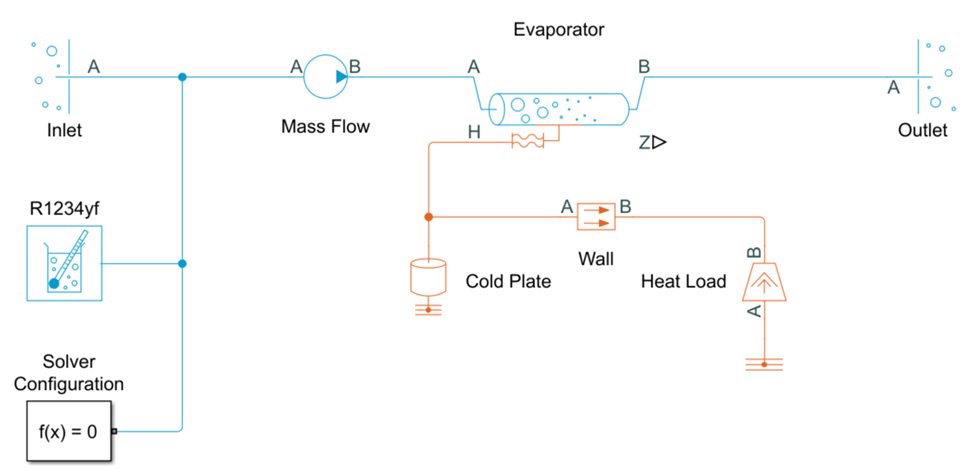

Figure 5: The test harness assembly for the evaporator/cold plate.

#### Trying out the Simulation

Now we have a test harness model for the evaporator/cold plate assembly, we need to simulate it and evaluate the results to ensure our model is plausible. A good place to start is by adding pressure and specific enthalpy sensors at the A and B ports of the evaporator pipe and sending these to a **P-H Diagram (2P)** block. This will allow us to determine if the evaporator is functioning properly. 

In our model, we’ll create a subsystem for these sensors because we’ll be using them extensively throughout the modeling process to come. The pressure/specific enthalpy (p/h) sensor subsystem is shown in Figure 6. 

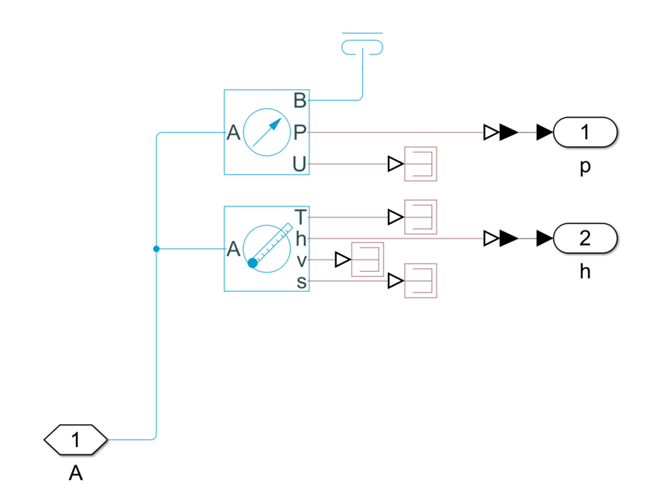

Figure 6: Sensor subsystem for pressure and specific enthalpy. We place these in a subsystem which can be replicated throughout the model as needed.

evaporatorParams         % load all the parameters necessary
step1_EvaporatorHarness  % open the evaporator test harness with sensors

Step 1: Copy in the Evaporator Harness system you built and connect the sensors as directed. You can select the entire system at once by left-clicking and dragging to select an entire region. 

Step 2: Run the model using the Run icon,  . 

Step 3: Look at the results of the simulation plotted on the P-H Diagram. As you can see, the pressure is consistently around 221 kPa while the enthalpy change is more dramatic moving from 265 kJ/kg at the inlet and 361 kJ/kg at the outlet. In the scope, you can see that the temperature rises slightly from 263K at the inlet to 268K at the outlet. 

 **Reflect**.

- Which states of matter are present in this system at the inlet? At the outlet?

- Why does the simulation create a static result?

We can extract data from this simulation:

% Check that you have run the simulation
if ~exist("out","var")
    warning("You didn't run the model from Simulink.")
else
% Timing data
tData = out.simlog_step1_EvaporatorHarness.Evaporator.z_mix.series.time;

% The fraction of vapor-liquid mix at each time step
z_mixData = out.simlog_step1_EvaporatorHarness.Evaporator.z_mix.series.values;

% The fraction of superheated vapor at each time step
z_vapData = out.simlog_step1_EvaporatorHarness.Evaporator.z_vap.series.values;
end

**Exercise. **Use this data to plot the fractions of vapor-liquid and superheated vapor in the evaporator component in steady state. 

Your result should look like:

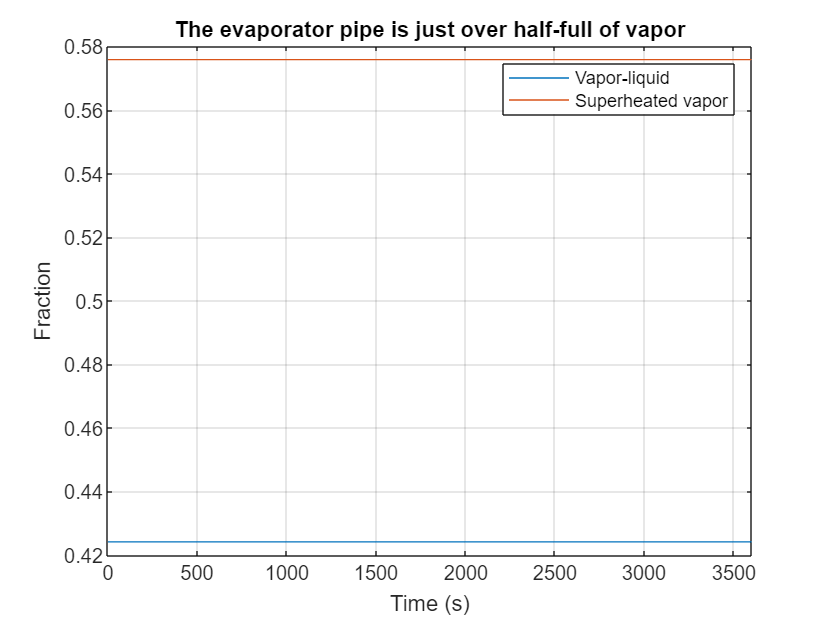

## Compressor Model

Now we can move from the Evaporator subsystem to the Compressor subsystem. 

In our calculations in the previous section, we estimated a mass flow rate of the compressor via Equation $(\star)$ to be:

mdotref

 We now need to define a compressor which can deliver this mass flow rate under the estimated evaporator pressure, `pevap`, the estimated condenser pressure, `pcond`, and the inlet specific enthalpy, `hout`, coming from the evaporator.

Pevap
Pcond
hout

  **Try**. 

- Open Simscape 

ssc_new

and add 

- a **Postive-Displacement Compressor (2P)** block. (**Simscape **$\bf{\rightarrow}$** Fluids**$\bf{\rightarrow}$**Two-PhaseFluid**$\bf{\rightarrow}$**Fluid Machines**)

- a **Mechanical Rotational Reference** block connected to the C port of the compressor (**Foundation Library **$\bf{\rightarrow}$** Mechanical**$\bf{\rightarrow}$**Rotational Elements**)

- an **Ideal Angular Velocity Source** block with the C and R ports connected to the C and R ports, respectively, of the compressor. (**Foundation Library **$\bf{\rightarrow}$** Mechanical**$\bf{\rightarrow}$**Mechanical Sources**)

- a **PS Constant **block connected to the S port of the angular velocity source. 

 **Pro-tip. **You can flip a selected block up-down (or left-right) by opening the context menu and selecting Format $\bf{\rightarrow}$ Flip block $\bf{\rightarrow}$ Up-Down (or Left-Right).

You also need to build or copy in from the Evaporator Harness:

- two **Reservoir (2P)** blocks to serve as the inlet, connected to the A port on the compressor, and the outlet, connected to the B port on the compressor (**Simscape **$\bf{\rightarrow}$** Fluids**$\bf{\rightarrow}$**Two-PhaseFluid**$\bf{\rightarrow}$**Elements)**

- a **Two-Phase Fluid Predefined Properties (2P) **block (**Simscape **$\bf{\rightarrow}$** Fluids**$\bf{\rightarrow}$**Two-PhaseFluid**$\bf{\rightarrow}$**Utilities**) set to R1234yf to provide the refrigerant. Connect this block to the inlet-to-compressor line. 

Set the parameters of each block appropriately:

1.** Reservoir (2P) **block

Name: Inlet

Parameter Settings: 

- Reservoir pressure specification:   specified pressure

- Reservoir pressure:                        Value: `p1_comp`       **Units: kPa**

- Reservoir energy specification:      specified enthalpy

- Reservoir specific enthalpy:           Value: `h1_comp`       **Units: kJ/kg**

- Cross-sectional area:                     Value: `a_evap`         **Units: cm^2**

2.** Reservoir (2P) **block

Name: Outlet

Parameter Settings: 

- Reservoir pressure specification:   specified pressure

- Reservoir pressure:                        Value: `p2_comp`       **Units: kPa**

- Reservoir pressure $\rightarrow$ Configurability:   Run-time

- Reservoir energy specification:      specified enthalpy

- Reservoir specific enthalpy:           Value: `h2_comp`       **Units: kJ/kg**

- Cross-sectional area:                     Value: `a_cond`         **Units: cm^2**

3. **Two-Phase Fluid Predefined Properties (2P)**

Name: R1234yf

Parameter Settings:

- Two-phase fluid: R-1234yf

4. **Solver Configuration**

Parameter Settings:

- Start simulation from steady state:      true (checked)

5. **PS Constant**

Name: Speed

Parameter Settings:

- Constant:                   Value: `N_0`

- Configurability:          Run-time

6.  **Postive-Displacement Compressor (2P)**

Name: Compressor

Parameter Settings:

- Displacement specification:       Nominal mass flow rate and shaft speed

- Nominal mass flow rate:             Value: `mdot_comp`      Units: kg/s

- Nominal shaft speed:                  Value: `N_comp`            Units: rpm

- Nominal inlet pressure:               Value: `p_nom_in`        **Units: kPa**

- Nominal inlet temperature:          Value: `T_nom_in`        Units: K

- Nominal volumetric efficiency:     Value: `eta_v` 

- Nominal pressure ratio:               Value: `pr_nom`

- Polytropic exponent:                    Value: `gamma1234yf` 

- Mechanical efficiency:                 Value: `eta_m`

- Inlet area at port A:                      Value: `a_evap      `**Units: cm^2**

- Outlet area at port B:                   Value: `a_cond      `**Units: cm^2**

Your test harness model for the compressor should look like:

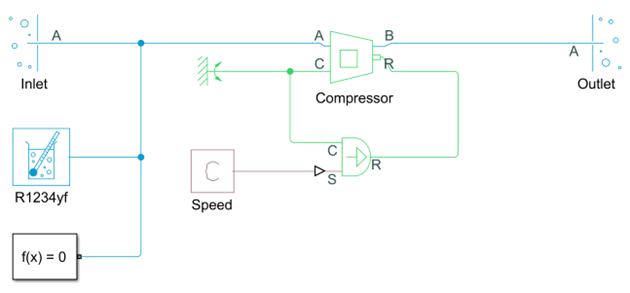

Some parameter values are set to Run-time. This will allow us to sweep the compressor through a series of simulations with different speeds and pressure ratios and generate its map once it has been parameterized.

Note that the mechanical parts here are green, while the refrigerant flows along the blue path. 

### ** Example:** Programmatically Testing the Compressor

As with the evaporator, testing the compressor requires adding additional sensors and comparing the simulation results to expected values. For the compressor, we'll test a range of values programmatically.

% Open the model with sensor attachments
mdl = 'step2_CompressorHarness';
open_system(mdl);

% Load the parameters
compressorParams;

Step 1: Copy and paste the compressor harness that you built and connect the sensors, as directed.

Step 2: Set up the design of experiments (DOE) for the parameter sweep. The goal is to sweep the compressor speed from 400 to 4000 rpm and the outlet pressure from 800 to 2400 kPa. This will exercise the compressor across pressure ratios from about 3 to 11, which should provide a reasonable map for the expected operating conditions. The key lines for setting up the DOE are initializing the set of values and creating the matrices of all sets of parameters.

N_lis = 400:400:4000;             % [rpm]
p2_lis = 800:400:2400;            % [kPa]

Programmatically determine the dimensionality of these experiments:

N_N = numel(N_lis);
N_p2 = numel(p2_lis);
N_sim = N_N*N_p2;

Create `N_N` by `N_p2` matrices called `N_mat` and `p2_mat` containing the necessary pairs of parameter values for every experiment in the set:

[N_mat, p2_mat] = ndgrid(N_lis, p2_lis);

Once the DOE is formulated, we can create a Simulink.SimulationInput object, which will be used to set the parameters of the model during a sequence of Simulink runs:

simin(1:N_sim) = Simulink.SimulationInput(mdl);

Set up the parameters used by the model:

try
for k = 1:N_sim
  simin(k) = simin(k).setBlockParameter([mdl '/Speed'], ...
                                        'constant', num2str(N_mat(k)));
  simin(k) = simin(k).setBlockParameter([mdl '/Outlet'], ...
                             'reservoir_pressure', num2str(p2_mat(k)));
end
catch ME
    if (strcmp(ME.identifier,'Simulink:Commands:InvSimulinkObjectName'))
        warning("You have not yet built the model")
    else
        warning("Unexpected error.")
        rethrow(ME)
    end
end

Run the simulations

pval = get_param(bdroot, 'SimscapeLogOpenViewer');
set_param(bdroot, 'SimscapeLogOpenViewer', 'off');
simout = sim(simin, 'ShowSimulationManager', 'off', 'UseFastRestart', 'on');
set_param(bdroot, 'SimscapeLogOpenViewer', pval);


#### Extract the simulation results and create the plots 

mdot = N_mat*0;
fp = mdot;
try
for k = 1:N_sim
  % Get the last elements of the mass flow and fluid power vars
  mlog = simout(k).simlog_step2_CompressorHarness.Compressor.mdot_A.series.values('kg/s');
  mdot(k) = mlog(end);
  fplog = simout(k).simlog_step2_CompressorHarness.Compressor.fluid_power.series.values('kW');
  fp(k) = fplog(end);
end
catch ME
    if (strcmp(ME.identifier,'MATLAB:structRefFromNonStruct'))
        warning("You have not yet built the model or you have errors in your simulation.")
    elseif (strcmp(ME.message,'Unrecognized field name "simlog_step2_CompressorHarness".'))
        warning("You have errors in your simulation. Did you insert the compressor harness properly?")
    else
        warning("Unexpected error.")
        rethrow(ME)
    end
end

% Create the legend entries for the plots. 
legs = N_lis + " rpm";
figure
plot(mdot, p2_lis/p1_comp)
grid on
xlabel('$\dot{m}$ [kg/s]', 'interpreter', 'latex') 
ylabel('$p_2/p_1$ [1]', 'interpreter', 'latex') 
title('Mass Flow Map');
legend(legs, 'location', 'EastOutside')


From the Mass Flow Map plot, we can see the flow rates are relatively insensitive to upstream pressure, which makes sense for this type of compressor because it represents a reciprocating compressor. We would expect that the motor would undergo torque stall when the required power exceeded its capability. Since we’re using a speed source, sufficient torque will always be provided. Measuring this would allow one to size an electric motor, but this is beyond the scope of the work here.

figure
plot(fp, p2_lis/p1_comp)
grid on
xlabel('P [kW]', 'interpreter', 'latex') 
ylabel('$p_2/p_1$ [1]', 'interpreter', 'latex') 
title('Required Fluid Cooling Power');
legend(legs, 'location', 'EastOutside')

In the Required Fluid Cooling Power plot, we see the amount of power added to the fluid as it flows through the compressor as a function of speed and pressure ratio. This plot suggests the compressor could add a little more than 0.6 kW of heat to the fluid which will have to be accounted for in the condenser. Nominally, we expect the added heat to be around 0.4-0.5 kW for the design condition (speed = 3600 rpm pressure ratio = 6-7) as can be seen from the plot. We will account for this when we design the condenser in the next section.

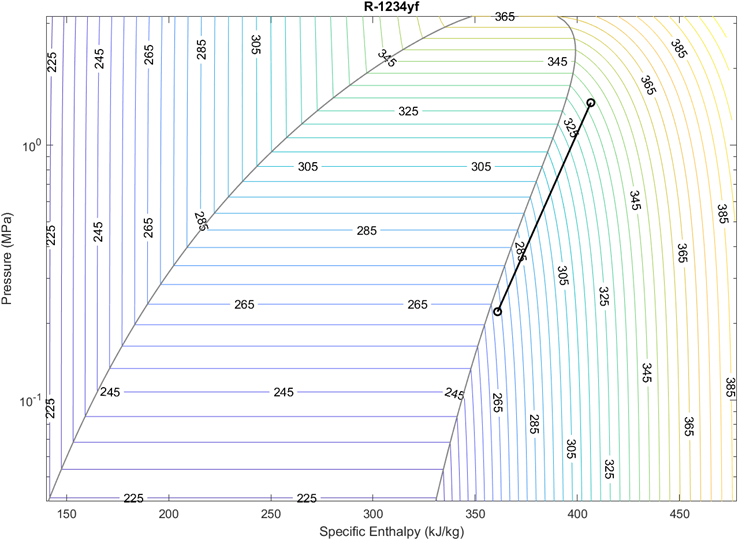

Figure 7: Pressure-enthalpy diagram for the compressor under nominal operating conditions.

Double-clicking on the P-H Diagram (2P) block shows the p/h diagram for the compressor at the nominal operating condition, as shown in Figure 7. As we might expect, the fluid heats as the pressure is increased because the compressor is performing work on it. The resulting outlet state is indicated by the upper right circle on the plot.

 **Reflect**.

- Does the compressor run before or after the evaporator in the refrigeration cycle? 

- In what direction is this line oriented? Why? 

## Condenser

Now that we have set up the evaporator and compressor and determined their approximate heat loads, we can parameterize the condenser for the system. The evaporator and compressor will add about 1 kW and 0.5 kW of heat to the refrigerant, respectively, which means the condenser should be designed to dissipate about 1.5 kW of heat from the refrigerant to the environment. The worst-case scenario given in our design specification is when the environmental temperature is at 40$^{\circ}$C, so we will parameterize the condenser under those conditions.

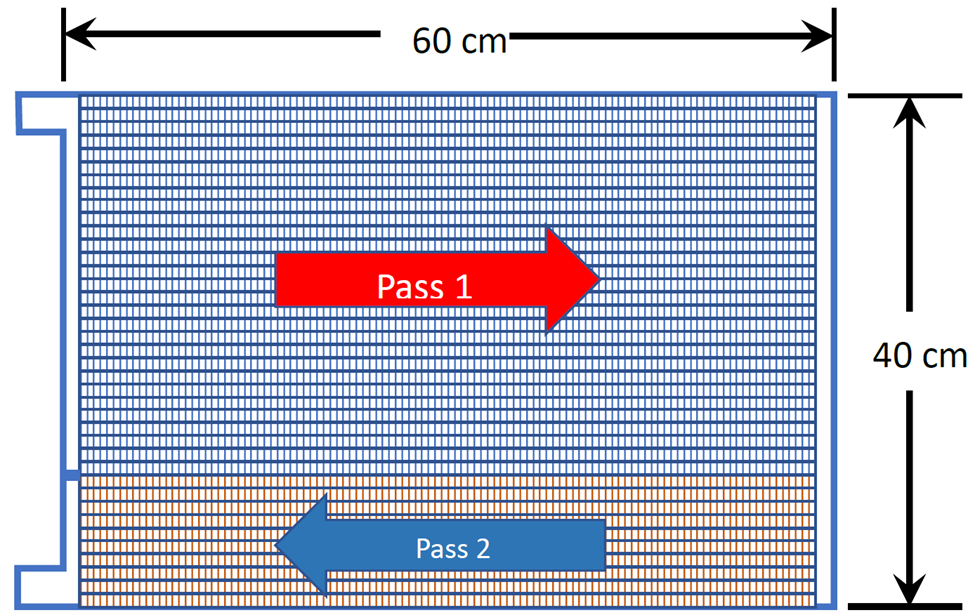

Figure 8: Two-pass condenser schematic. The refrigerant enters at the top and passes from left to right in the upper 30 banks of tubes, then right to left in the lower 10 banks of tubes. There are 3 manifolds for the refrigerant, 2 on the left and one on the right. The air flows perpendicular the plane of the document.

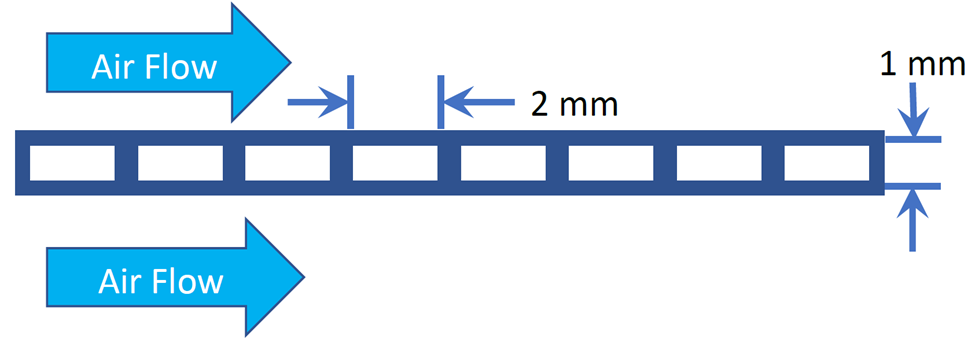

Figure 9: Refrigerant tube cutaway. The refrigerant flows into the plane of the document in the 8 channels. There are fins on the top and bottom of each bank, which the air flows through to dissipate heat released by the condensing refrigerant.

The condenser to be modeled is a two-pass model with 30 banks in the first pass and 10 in the second pass. The tube banks are arranged 8-per-row in line with fins that expel heat to the crossflow air stream. The configuration of the two refrigerant passes is shown in Figure 8 and the tube bank arrangement is shown in Figure 9. Assume the fins are independent of each other and aligned vertically with a density of 5 fins per cm, which is a reasonable approximation for this type of condenser hardware. This allows the calculation of $a_{\text{fins}}$.

The entrance and exits of the condenser and the connection between its two passes are represented as pipes. These pipes are not thermally connected, but serve to add capacitance to the condenser, which is key to preventing the tubes from flooding during high temperature operations once the condenser is placed into the closed-loop system.

  **Try**. 

- Open Simscape 

ssc_new

and add

- three **Pipe (2P)** blocks. (**Foundation Library**$\bf{\rightarrow}$**Two-Phase Fluid**$\bf{\rightarrow}$**Elements**)

- two **Condenser Evaporator (2P-MA)** blocks (**Fluids**$\bf{\rightarrow}$**Fluid Network Interfaces**$\bf{\rightarrow}$**Heat Exchangers**)

to model the condenser.

You also need to build or copy in connections to the environment:

- two **Reservoir (2P)** blocks to serve as the inlet and the outlet for the refrigerant (**Simscape **$\bf{\rightarrow}$** Fluids**$\bf{\rightarrow}$**Two-PhaseFluid**$\bf{\rightarrow}$**Elements)**

- a **Two-Phase Fluid Predefined Properties (2P) **block (**Simscape **$\bf{\rightarrow}$** Fluids**$\bf{\rightarrow}$**Two-PhaseFluid**$\bf{\rightarrow}$**Utilities**) set to R1234yf to provide the refrigerant.  

- a **Mass Flow Rate Source (2P) **block to regulate the inflow of the refrigerant (**Simscape **$\bf{\rightarrow}$** Fluids**$\bf{\rightarrow}$**Two-PhaseFluid**$\bf{\rightarrow}$**Sources)**

- four **Reservoir (MA)** blocks to model the inflow and outflow of air (**Foundation Library**$\bf{\rightarrow}$**Moist Air**$\bf{\rightarrow}$**Elements**)

- two **Mass Flow Rate Source (MA) **blocks to regulate the inflow of the air (**Foundation Library**$\bf{\rightarrow}$**Moist Air**$\bf{\rightarrow}$**Sources)**

Once you have connected your system you need to set up names and parameter values.

1.** Reservoir (2P) **block

Name: Inlet

Parameter Settings: 

- Reservoir pressure specification:   specified pressure

- Reservoir pressure:                        Value: `p0_cond`      **Units: kPa**

- Reservoir energy specification:      specified enthalpy

- Reservoir specific enthalpy:           Value: `h0_cond`      Units: kJ/kg

- Cross-sectional area:                     Value: `a_cond    `**Units: cm^2**

2.** Reservoir (2P) **block

Name: Outlet

Parameter Settings: 

- Reservoir pressure specification:   specified pressure

- Reservoir pressure:                        Value: `p0_cond`      **Units: kPa**

- Reservoir pressure $\rightarrow$ Configurability:  Run-time

- Reservoir energy specification:      specified enthalpy

- Reservoir specific enthalpy:           Value: `h0_cond`      Units: kJ/kg

- Cross-sectional area:                     Value: `a_cond    `**Units: cm^2**

3. **Two-Phase Fluid Predefined Properties (2P)**

Name: R1234yf

Parameter Settings:

- Two-phase fluid: R-1234yf

4. **Solver Configuration**

Parameter Settings:

- Start simulation from steady state:      true (checked)

5. **Mass Flow Rate Source (2P)**

Parameter Settings:

- Mass flow rate:                            Value: `mdot_cond`  Units: kg/s

- Cross-sectional area at port A     Value: `a_cond    `**Units: cm^2**

- Cross-sectional area at port B     Value: `a_cond    `**Units: cm^2**

6. **Reservoir (MA)**

Name: Air In 1

Connected to:  port A of Air Flow 1 

Parameter Settings:

- Reservoir trace mass gas fraction:    0.00

- Reservoir temperature specification: Specified temperature

- Reservoir temperature:                Value: `T_air_cond`      **Units: degC**

- Cross-sectional area at port A:    Value: `a_x_cond(1)  `**Units: cm^2** 

7. **Reservoir (MA)**

Name: Air In 2

Connected to:  port A of Air Flow 2 

Parameter Settings:

- Reservoir trace mass gas fraction:    0.00

- Reservoir temperature specification: Specified temperature

- Reservoir temperature:                Value: `T_air_cond`      **Units: degC**

- Cross-sectional area at port A:    Value: `a_x_cond(2)  `**Units: cm^2** 

8. **Reservoir (MA)**

Name: Air Out 1

Connected to:  port B2 of Pass 1 

Parameter Settings:

- Cross-sectional area at port A:   Value: `a_x_cond(1)  `**Units: cm^2** 

9. **Reservoir (MA)**

Name: Air In 2

Connected to:  port B2 of Pass 2 

Parameter Settings:

- Cross-sectional area at port A:   Value: `a_x_cond(2)  `**Units: cm^2** 

10. **Mass Flow Rate Source (MA)**

Name: Air Flow 1

Connected to:  port A to Air In 1 and port B to port A2 of Pass 1

Parameter Settings:

- Power added:                             None

- Mixture mass flow rate:              Value: `mdot_air_cond(1)`  Units: kg/s

- Cross-sectional area at port A:   Value: `a_x_cond(1)  `**Units: cm^2**

- Cross-sectional area at port B:   Value: `a_x_cond(1)  `**Units: cm^2**

11. **Mass Flow Rate Source (MA)**

Name: Air Flow 2

Connected to:  port A to Air In 2 and port B to port A2 of Pass 2

Parameter Settings:

- Power added:                             None

- Mixture mass flow rate:              Value: `mdot_air_cond(2)`  Units: kg/s

- Cross-sectional area at port A:   Value: `a_x_cond(2)  `**Units: cm^2**

- Cross-sectional area at port B:   Value: `a_x_cond(2)  `**Units: cm^2**

12. **Pipe (2P)**

Name: Manifold 1

Connected to: port B to port B on the Mass Flow Rate Source (2P), port A to port A1 of Pass 1

Parameter Settings:

- Pipe length:                   Value: `l_man(1)`    **Units: cm**

- Cross-sectional area:    Value: `a_man`          **Units: cm^2**

- Hydraulic diameter:       Value: `d_man`          **Units: cm**

- Effects and Initial Conditions$\rightarrow$Initial fluid energy specification:  specific enthalpy

- Effects and Initial Conditions$\rightarrow$Initial specific pressure:    Value: `p0_cond`  **Units: kPa**

- Effects and Initial Conditions$\rightarrow$Initial specific enthalpy:    Value: `h0_cond`  Units: kJ/kg

13. **Pipe (2P)**

Name: Manifold 2

Connected to: port B to port B1 of Pass 1; port A to port A1 of Pass 2

Parameter Settings:

- Pipe length:                   Value: `l_man(2)`    **Units: cm**

- Cross-sectional area:    Value: `a_man`          **Units: cm^2**

- Hydraulic diameter:       Value: `d_man`          **Units: cm**

- Effects and Initial Conditions$\rightarrow$Initial fluid energy specification:  specific enthalpy

- Effects and Initial Conditions$\rightarrow$Initial specific pressure:    Value: `p0_cond`  **Units: kPa**

- Effects and Initial Conditions$\rightarrow$Initial specific enthalpy:    Value: `h0_cond`  **Units: kJ/kg**

14. **Pipe (2P)**

Name: Manifold 3

Connected to: port B to port B1 of Pass 1; port A to port A of Outlet

Parameter Settings:

- Pipe length:                   Value: `l_man(3)`    **Units: cm**

- Cross-sectional area:    Value: `a_man`          **Units: cm^2**

- Hydraulic diameter:       Value: `d_man`          **Units: cm**

- Effects and Initial Conditions$\rightarrow$Initial fluid energy specification:  specific enthalpy

- Effects and Initial Conditions$\rightarrow$Initial specific pressure:    Value: `p0_cond`  **Units: kPa**

- Effects and Initial Conditions$\rightarrow$Initial specific enthalpy:    Value: `h0_cond`  Units: kJ/kg

15. **Condenser Evaporator (2P-MA)**

Name: Pass 1

Connected to: port A1 to port A on Manifold 1; port B1 to port B on Manifold 2; port A2 to port B on Air Flow 1; port B2 to port A on Air Out 1

Parameter Settings:

In Configuration,

- Cross flow arrangement: Both fluids unmixed

- Cross-sectional area at port A1:   Value: `a_cond `         **Units: cm^2**

- Cross-sectional area at port B1:   Value: `a_cond `         **Units: cm^2**

- Cross-sectional area at port A2:   Value: `a_x_cond(1) `**Units: cm^2**

- Cross-sectional area at port B2:   Value: `a_x_cond(1) `**Units: cm^2**

In Two-Phase Fluid 1,

- Number of tubes:             Value: `N_tube_pass(1)`

- Total length of each tube:             Value: `l_tube`     **Units: cm**

- Tube cross section:                      Rectangular

- Tube width:                                   Value: `w_tube`     **Units: mm**

- Tube height:                                  Value: `h_tube`     **Units: mm**

- Initial fluid energy specification:   Specific enthalpy

- Initial two-phase fluid pressure:              Value: `p0_cond`  **Units: kPa**

- Initial two-phase fluid specific enthalpy:  Value: `h0_cond`  Units: kJ/kg

In Moist Air 2,

- Flow geometry:                                         Generic

- Minimum free-flow area:                           Value: `a_maflow(1)  `     **Units: cm^2**

- Heat transfer surface area without fins     Value: `a_x_httubes(1)`   **Units: cm^2**

- Moist air volume inside heat exchanger   Value: `v_ma(1)`                 **Units: cm^3**

- Coefficients [a,b,c] for a*Re^b*Pr^c         Value: `REPRabc`

- Total fin surface area:                               Value: `a_fins(1)`            Units: m^2

- Initial moist air temperature:                     Value: `T_air_cond`          **Units: degC**

16. **Condenser Evaporator (2P-MA)**

Name: Pass 2

Connected to: port A1 to port A on Manifold 2; port B1 to port B on Manifold 3; port A2 to port B on Air Flow 2; port B2 to port A on Air Out 2

Parameter Settings:

In Configuration,

- Cross flow arrangement: Both fluids unmixed

- Cross-sectional area at port A1:   Value: `a_cond `         **Units: cm^2**

- Cross-sectional area at port B1:   Value: `a_cond `         **Units: cm^2**

- Cross-sectional area at port A2:   Value: `a_x_cond(2) `**Units: cm^2**

- Cross-sectional area at port B2:   Value: `a_x_cond(2) `**Units: cm^2**

In Two-Phase Fluid 1,

- Number of tubes:             Value: `N_tube_pass(2)`

- Total length of each tube:             Value: `l_tube`     **Units: cm**

- Tube cross section:                      Rectangular

- Tube width:                                   Value: `w_tube`     **Units: mm**

- Tube height:                                  Value: `h_tube`     **Units: mm**

- Initial fluid energy specification:   Specific enthalpy

- Initial two-phase fluid pressure:              Value: `p0_cond`  **Units: kPa**

- Initial two-phase fluid specific enthalpy:  Value: `h0_cond`  Units: kJ/kg

In Moist Air 2,

- Flow geometry:                                         Generic

- Minimum free-flow area:                           Value: `a_maflow(2)  `     **Units: cm^2**

- Heat transfer surface area without fins     Value: `a_x_httubes(2)`   **Units: cm^2**

- Moist air volume inside heat exchanger   Value: `v_ma(2)`                 **Units: cm^3**

- Coefficients [a,b,c] for a*Re^b*Pr^c         Value: `REPRabc`

- Total fin surface area:                               Value: `a_fins(2)`            Units: m^2

- Initial moist air temperature:                     Value: `T_air_cond`          **Units: degC**

Your result should look like: 

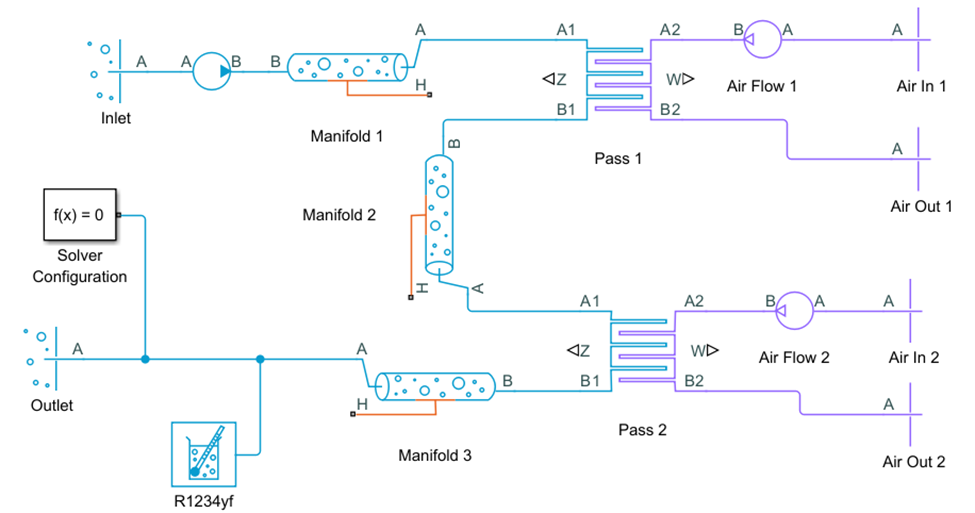

Note that the refrigerant passes through the blue blocks in series while the air passes through the purple blocks in parallel. This is why there are more air inlets and outlets required than there are refrigerant inlets and outlets. 

### Validate the Condenser Model

% Open the model with sensor attachments
mdl = 'step3_CondenserHarness';
open_system(mdl);

% Load the parameters
condenserParams;

Copy in the Condenser Harness model that you built, attach the sensors, and save the result.

% Run the simulation
try
simout = sim(Simulink.SimulationInput(mdl));
catch ME
    if (strcmp(ME.identifier,'physmod:simscape:engine:sli:extensible:NoSolverBlockConnected'))
        warning("You have not yet connected the model to the sensors. There is no Solver Block.")
    else
        warning("Unexpected error.")
        rethrow(ME)
    end
end

Figure 10: The pressure-enthalpy diagram for R-1234yf passing through our condenser.

Double-clicking on the P-H Diagram (2P) block shows the P-H diagram for the condenser at the nominal operating condition, as shown in Figure 10.

** Exercise.**

- What is the orientation of this path on the P-H diagram?

tf1 = checkCondenserPath("unknown");

         2. What is the state of the R-1234yf when it enters the condenser?

tf2 = checkCondenserState("unknown","input");

         3. What is the state of the R-1234yf when it leaves the condenser?

tf3 = checkCondenserState("unknown","output");

#### **Check the Condenser Fluid State Fractions**

  **Try**.  Run this section to generate a plot of the condenser fluid state fractions. Do they match what you expect from the P-H diagram?

if ~tf1 || ~tf2 || ~tf3
    warning("Please complete the exercise before continuing.")
elseif ~exist("simout","var")
    warning("You must successfully simulate the condenser to proceed.")
else
    % Extract the data from the simulation and scale data to %
    tData = simout.simlog.Condenser.Pass_1.Z.series.time;
    pass1z = simout.simlog.Condenser.Pass_1.Z.series.values*100;
    pass2z = simout.simlog.Condenser.Pass_2.Z.series.values*100;

    % Plot the data with varying colors and line styles
    % Increase the line width for visibility and set the y scale
    plot(tData,pass1z(:,3),"-","SeriesIndex",1,"LineWidth",2)
    grid on
    ylim([0 100])
    hold on
    plot(tData,pass1z(:,2),"--","SeriesIndex",2,"LineWidth",2)
    plot(tData,pass2z(:,2),"-.","SeriesIndex",3,"LineWidth",2)
    plot(tData,pass2z(:,1),":","SeriesIndex",4,"LineWidth",2)
    hold off

    % Add labels
    legend(["Pass 1 SHV" "Pass 1 VLE" "Pass 2 VLE" "Pass 2 SCL"])
    title("Condenser Fluid State Fractions")
    xlabel("Time t (s)")
    ylabel("Z (%)")
end

As the fluid moves through the first pass of the condenser tubes, it begins to condense and enters the vapor-liquid equilibrium dome. In the second pass, the fluid crosses the saturated liquid boundary and leaves as a sub-cooled liquid. To ensure the latter is true, we plot selected state fractions of the fluids in the condenser passes in Figure 19. From this figure we can see about 56% of the length of Pass 1 contains fluid in the super-heated vapor (SHV) state and 44% of Pass 1 contains fluid in the vapor-liquid equilibrium (VLE) state. In pass 2 we see 86% of the fluid is in the VLE state and the remaining 14% is in the sub-cooled liquid (SCL) state. We can potentially use this information later to determine whether the size of our device is optimal.

## Closing the Loop

Now that we have the evaporator, compressor and condenser roughly sized, we’re ready to start closing the loop with the expansion device. It is important to note that the former three devices all change the system energy, whereas the expansion device is normally treated as isenthalpic. 

** Exercise.**

Which of the following P-H diagrams do you expect for this closed system?

a) 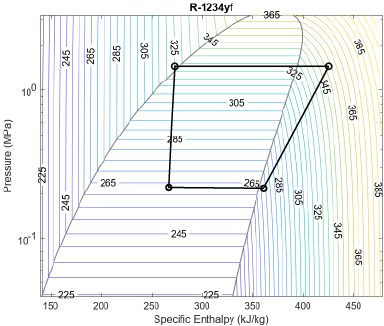   b)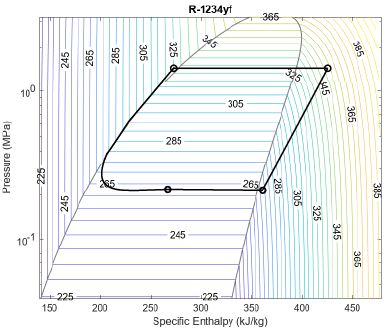    c) 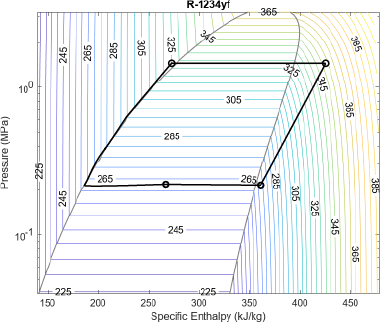

checkSystem("unknown")

**Isenthalpic** means that the specific enthalpy at the outlet to the condenser and the inlet to the evaporator should be the same. Before we close the loop, we’ll set up a system to ensure this for the steady state conditions specified in the design. Once the evaporator/compressor/condenser system is validated we’ll parameterize and insert an expansion valve.

### Energy Cycle Validation

To ensure the parameters of evaporator, compressor and condenser are well-sized for their use together, we assemble them into a new harness model. This model is called `step4_EvapCompCondHarness.slx`, and it is shown in Figure 11. Note we have assembled the individual parts to mirror the schematic in Figure 1, with the evaporator on the bottom, the condenser as a subsystem at the top and the compressor along the right-hand side. This allows us to put the sensors in the order that they show up in the pressure/enthalpy diagram.

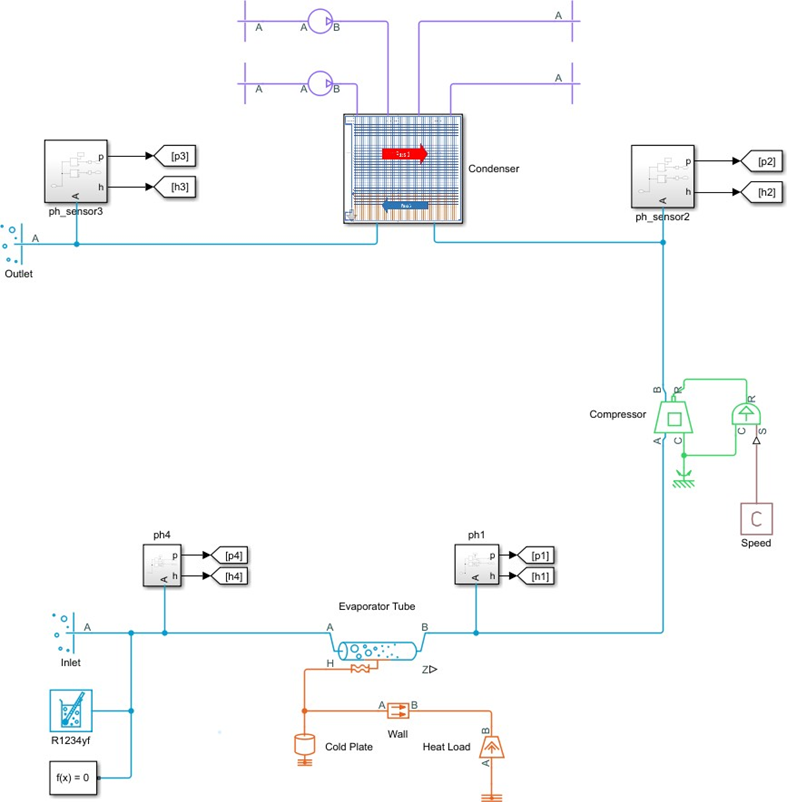

Figure 11: Energy balance test harness. This test harness provides a check to see that the evaporator, compressor, and condenser are in balance for the design cycle at steady state. Boundary conditions are set at the Inlet and Outlet blocks.

The block parameters for the Inlet and Outlet boundary condition blocks are given in `evapCompCondParams.m`. These are the approximate steady state values for the design cycle. Note the model still uses the steady state option in the Solver Configuration block. Once we add the final physical element we will switch this off to model the proper dynamic behavior. 

% Define the model to work with
mdl = 'step4_EvapCompCondHarness';

% Open the model with sensor attachments
open_system(mdl);

% Run the simulation
sim(mdl);

The resulting pressure/enthalpy diagram for the assembly is shown. As can be seen in this plot, the simulation behaves in accordance with the design parameters. The evaporator outlet is slightly super-heated, and the condenser outlet is slightly sub-cooled as expected.

  **Try**. Check the mass flow for this system using the Simscape Results Explorer (`sscexplorer). `

- Compressor $\rightarrow$ `mdot_A`

- CondOut $\rightarrow$ `mdot_A`

- EvapIn $\rightarrow$ `mdot_A`

- Evaporator Tube $\rightarrow$ `mdot_A`

The design value of a mass flow of 0.0104 kg/s should be close to (with 2%) your simulated values. 

## Expansion Valve

Now that we have determined the system energetics are in balance we can parameterize and insert the expansion valve. In our application we will use an **Orifice (2P)** block (Simscape→Fluids→Two-Phase Fluid→Valves & Orifices→Orifice (2P)). In order to have enough flexibility for our controller, we’ll size the valve so it has our approximate nominal desired flow rate (~0.01 kg/s) when it is halfway open and the upstream and downstream pressures are 1464.7 kPa and 221.78 kPa, respectively. The parameters and boundary conditions for the valve use specific enthalpy inlet condition specifications as well as the usual "Start from steady state" solver configuration. The initialization script is called `valveParams.m`. The test harness model for the valve is called `step5_ValveHarness.slx`. As with the other harness models, we provide inlet and outlet reservoirs at the nominal operating conditions and solve at steady state. To validate the range of flows, we start the system with the valve fully open and use a ramp function to close it fully.

% Define the model to work with
mdl = 'step5_ValveHarness';

% Load the parameters
valveParams;
% Open the model with sensor attachments
open_system(mdl);

Run the simulation using a simple linear profile from the step function:

simout = sim(mdl);

After running the simulation, extract data:

opening_fraction = simout.simlog_step5_ValveHarness.Valve.opening_fraction.series.values;
opening_length = opening_fraction*valve_max_open;
mdot = simout.simlog_step5_ValveHarness.Valve.mdot_A.series.values;

and plot the results:

plot(opening_length,mdot,"LineWidth",2)
yline(0.0104,"y--","LineWidth",2)

% Label the plot
title("Valve Characteristic")
xlabel("Position (mm)")
ylabel("Mass Flow Rate (kg/s)")
legend(["Simulated Valve" "Designed Mass Flow Rate"],"Location","northwest")

## Inserting the Valve

Now that we have parameterized the valve, we can insert it into our model and close the loop. Since all the components were put in test harnesses and sized appropriately, this step is can be performed by placing the valve from `step5_ValveHarness.slx` into the `step4_EvapCompCondHarness.slx` model between the condenser outlet and evaporator inlet and removing the reservoirs. 

% Open the models with sensor attachments
mdl = 'step6_ClosedLoopHarness';
open_system(mdl);

% If you do not have step5_ValveHarness open, 
% also uncomment and run this
% valve_mdl = 'step5_ValveHarness';
% open_system(valve_mdl);

  **Try**. Copy the Valve block into the `step6_ClosedLoopHarness` system. 

- Connect the A port to the output (L1 Connector) of the Condenser. 

- Connect the B port to the A port for the Evaporator Tube.

- Add a Simulink-PS Converter block (**Utilities**), connect the output port to the S port of the Valve, and set the input signal unit to mm.  

- Add a Constant block (**Simulink**), connect it to the input side of the Simulink-PS Converter and set it to 2.5.

- Delete the EvapIn and CondOut blocks. 

- Set the "Start simulation from steady state" field of the Solver Configuration block to false.

Ensure that Sensor 3 is connected between the condenser and the valve. Then run the model:

closedLoopParams

sim(mdl);

If you have done this correctly, running this code generates errors. Why?

When we run the model, we note that it quickly diverges, and we get a simulation failure at around 0.8 seconds. The error message mentions that we have exceeded the maximum valid specific internal energy for parts of our system. Watch the evolution of the system on the P-H diagram. As we approach the failure time, the P-H diagram is:

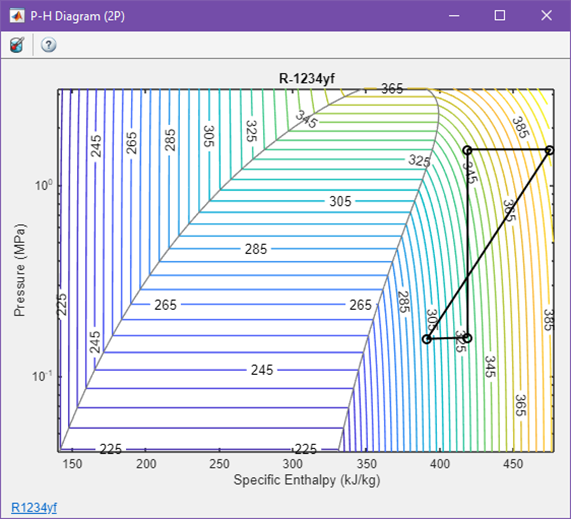

Figure 12: The closed loop P-H diagram at Time=0.8124 seconds. Notice the circle in the upper left corner is about to leave the diagram. This indicates the model is about to exceed the maximum specific enthlapy in our fluid propery tables.

** Exercise. **Figure 12 indicates one of the sensors in the system is running off the fluid property lookup tables we have in place. Which one is it? 

sensorBetweenComponents("unknown")

The root cause for the error is not in the sizing of the system components, but rather how we have defined its initial conditions. As we will see in the next section, our system is severely undercharged with refrigerant. If we were able to create a real system in this state, we would find it would rapidly overheat and fail catastrophically. In the next section, we’ll diagnose and fix the problem. In the simulation, we observe an unexpected set of initial conditions for the enthalpies that result in state diagram plots that should look incorrect to you, even at time 0.

## Charging the System

To understand the simulation failure, we first need to take account of the total system volume and amount of refrigerant in the `step6_ClosedLoopHarness.slx` model. To do this we can set the model Stop Time to zero and simulate it. Then we can interrogate the simulation log for blocks that have internal volume nodes. These are the blocks that have will have mass in the simulation and they are:

- Condenser manifolds – Pipe (2P)

- Condenser heat exchangers – Condenser Evaporator (2P-MA)

- Evaporator – 3-Zone Pipe (2P)

  **Try**. Make sure the model is open and its parameters are loaded, then simulate for zero seconds so the refrigerant blocks with volume compute their masses

mdl = "step6_ClosedLoopHarness";
closedLoopParams;
open_system(mdl);
out = sim(mdl, 'StopTime', '0');

Identify the condenser masses for the manifolds and heat exchanger blocks:

mm1 = out.simlog_step6_ClosedLoopHarness.Condenser.Manifold_1.mass.series.values('kg');
mm2 = out.simlog_step6_ClosedLoopHarness.Condenser.Manifold_2.mass.series.values('kg');
mm3 = out.simlog_step6_ClosedLoopHarness.Condenser.Manifold_3.mass.series.values('kg');
mp1 = out.simlog_step6_ClosedLoopHarness.Condenser.Pass_1.two_phase_fluid.mass.series.values('kg');
mp2 = out.simlog_step6_ClosedLoopHarness.Condenser.Pass_2.two_phase_fluid.mass.series.values('kg');


Identify the mass in the evaporator tube:

me = out.simlog_step6_ClosedLoopHarness.Evaporator_Tube.mass.series.values('kg');

** Exercise. **Compute the total mass, `mass_total` in kilograms:

mass_total = 0;
% % Solution
% mass_total = mm1 + mm2 + mm3 + mp1 + mp2 + me;     % [kg]
% % End Solution

Recall that the geometric dimensions we know are:

Compute the volume of the manifolds and heat exchangers in cubic meters:

  **Pro-tip**. The function [`sum`](matlab: doc sum) will add up all of the components of a vector.

v_manif = sum(a_man*l_man)/(100*100*100);                  % [m^3]
v_hx = sum(N_tube_pass*l_tube*a_tube)/(100*1000*1000);     % [m^3]

Compute the volume of the evaporator in cubic meters:

v_evap = l_evap*a_evap/(100*100);                          % [m^3]

Compute the total system volume, `v_total`, in cubic meters:

v_total = 0;
% % Solution
% v_total = v_manif + v_hx + v_evap;                         % [m^3] 
% % End Solutoin

Compute the system density `rho`. Ideally this should be between 200 and 300 $\frac{\text{kg}}{\text{m}^3}$ for R1234yf.

rho = 0;
% % Solution
% rho = mass_total/v_total;                                  % [kg/m^3]
% % End Solution
checkDensity(mass_total,v_total,rho)

** Exercise. **Given the calculated values of mass, volume and density, is this system currently undercharged or overcharged?

systemIs("unknown")

To compute the correct system density for the system at rest in some ambient condition, we need to consult the property tables for the fluid. In our case, we’ll start our system out in the worst-case environment at T=40$^{\circ}$C. 

load R1234yfData Pinit            % Pa
P0 = Pinit/1e3                    % kPa

This gives us the initial pressure condition for the pipes and heat exchangers.

** Exercise. **To be effective, when the system is at rest the refrigerant must be in the following state(s):

initialState("unknown");

With this in mind, we will specify the initial vapor quality in the pipes and heat exchangers. To compute the initial system quality, we can query a thermal properties database with temperature T=40$^{\circ}$C and density=200 kg/m^3. 

Alternately, if we know the vapor and liquid densities at the given temperature, we can interpolate to determine the initial quality. 

load R1234yfData rho_l rho_v          % kg/m^3
disp("For R1234yf at 40C we have a liquid density of rho_l=" + rho_l + ... 
    newline + "and a vapor density of rho_v=" + rho_v + ".")

To compute the vapor quality required to achieve our target density of $\rho_{\text{ref}}=200$ kg/m^3 we can use the following equation:


$$\rho_{\text{ref}} = \frac{1}{\frac{x_0}{\rho_v} + \frac{1-x_0}{\rho_l}},$$


and solve for $x_0$

rho_ref = 200;                        % kg/m^3
fun = @(x) rho_ref-1/(x/rho_v + (1-x)/rho_l);
x0 = fzero(fun,0.5)                   % initial quality fraction

## Running the Closed Loop

  **Try**. When we set the initial conditions for the properly charged system and run it, we can see that the system stabilizes to a good place that reflects our design. The steady-state cycle is shown in Figure 13. The condenser provides fully condensed refrigerant, and the evaporator is providing super-heated vapor to the compressor.

% Load the parameter values
closedLoopFixDensityParams


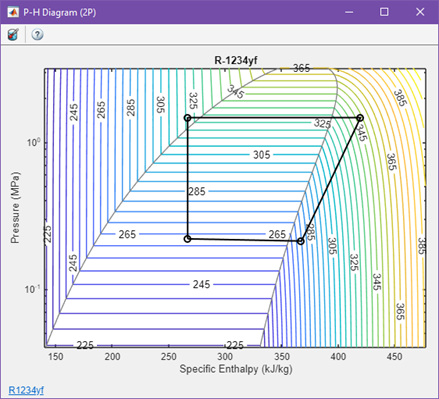

Figure 13: Thermodynamic cycle for the correctly charged closed-loop system.

[⇦ Return to the navigation page](matlab: OpenOverview)

## References

- **Lemmon, E.W., Bell, I.H., Huber, M.L., McLinden, M.O. ***NIST Standard Reference Database 23: Reference* *Fluid* *Thermodynamic* *and* *Transport* *Properties-REFPROP,* *Version**10.0,* *National* *Institute* *of Standards and Technology. *Gaithersburg, MD, USA : s.n., 2018.

- **Bell,** **Ian** **H.** **and** **Wronski,****Jorrit** **and** **Quoilin,****Sylvain** **and** **Lemort,****Vincent. **Pure and Pseudo-pure Fluid Thermophysical Property Evaluation and the Open-Source Thermophysical Property Library CoolProp. *Industrial & Engineering Chemistry Research. *2014, Vol. 53, 6, pp. 2490-2508.

function initialState(opt)
if opt == "unknown"
disp("This is the default value. Please select a state.")
elseif opt == "vapor-liquid mixture"
    disp("That is correct. This allows sufficient phase transition to perform" + ...
        newline + "the cooling task.")
elseif opt == "depends on the component"
    disp("That is incorrect. The state (or mix of states) must be the same.")
elseif opt == "vapor"
    disp("That is incorrect. If the initial state was vapor, it could not form sufficient liquid.")
elseif opt == "liquid"
    disp("That is incorrect. If the initial state was liquid, it could not vaporize" + ... 
        newline + "because there is no space.")
else
    disp("How did you get here?")
end
end

function systemIs(opt)
if opt == "unknown"
    disp("This is the default value. Please select undercharged or overcharged.")
elseif opt == "undercharged"
    disp("The current density is about 56 kg/m^3 which is less than 200 kg/m^3." + ...
        newline + "You are correct, this system is undercharged.")
elseif opt == "overcharged"
    disp("The current density is about 56 kg/m^3 which is less than 200 kg/m^3." + ...
        newline + "A system is overcharged if the density is too high."  + ...
        + newline + "This system is not overcharged.")
end
end

function checkDensity(my_mass_total,my_v_total,my_rho)
load densityValues.mat mass_total v_total rho
if my_mass_total == mass_total && my_v_total == v_total && my_rho == rho
    disp("Mass of Refrigerant: " + my_mass_total + " kg");
    disp("Total System Volume: " + my_v_total + " m^3");
    disp("System Density: " + my_rho + " kg/m^3");
elseif my_mass_total == 0 && my_v_total == 0 && my_rho == 0
    disp("These are the default values. Please compute real values.")
elseif abs(my_rho - 386.7343) < 1e-1
    disp("You are running your model in steady-state without the valve.")
    disp("Please open the Solver Configuration block and uncheck 'Start simulation from steady state'.")
else
    if my_mass_total ~= mass_total
        disp("Your total mass is incorrect.")
    end
    if my_v_total ~= v_total
        disp("Your total volume is incorrect.")
    end
    if my_rho ~= rho
        disp("Your density is incorrect.")
    end
end
end

function tf = checkCondenserPath(opt)
tf = 0;
if opt == "unknown"
    disp("This is the default. Please select a direction.")
elseif opt == "left to right"
    disp("Remember that the R-1234yf is flowing from the compressor into" + ...
        newline + "the condenser. Where is the path of the compressor?")
elseif opt == "right to left"
    disp("That is correct. The R-1234yf has just come from the compressor" + ...
        newline + "which raised the pressure and is passing through the condenser" + ...
        newline + "which lowers the enthalpy.")
    tf = 1;
else
    disp("How did you get here? That was an unexpected option.")
end
end

function tf = checkCondenserState(opt,dir)
tf = 0;
if opt == "unknown"
    disp("This is the default. Please select a state.")
elseif opt == "solid"
    disp("This diagram does not include the solid state. Please try again.")
elseif opt == "sub-cooled liquid"
    if dir == "output"
        disp("That is correct.")
        tf = 1;
    else
        disp("The sub-cooled liquid region is on the left." + ...
            newline + "Where is the initial state? And the final state?" + ...
            newline + "Please try again.")
    end
elseif opt == "liquid-vapor mixture"
    disp("The liquid-vapor mixture region is in the center." + ...
        newline + "Where is the initial state? And the final state?" + ...
        newline + "Please try again.")
elseif opt == "super-heated vapor"
    if dir == "input"
        disp("That is correct.")
        tf = 1;
    else
        disp("The super-heated vapor region is on the right." + ...
            newline + "Where is the initial state? And the final state?" + ...
            newline + "Please try again.")
    end
elseif opt == "plasma"
    disp("This diagram does not include the solid state. Please try again.")
else
    disp("How did you get here? That was an unexpected option.")
end
end

function checkSystem(opt)
if opt == "a"
    disp("That is correct. Isenthalpic means that the enthalpy should be constant.")
elseif opt == "unknown"
    disp("This is the default. Please select a P-H diagram.")
else
    disp("No, this is not an isenthalpic line. Please try again.")
end
end

function sensorBetweenComponents(opt)
if opt == "unknown"
    disp("This is the default. Please select Sensor 1, 2, 3, or 4.")
elseif opt == "ph2"
    disp("This is correct.")
else
    disp("This is not correct. Use the Simscape Results Explorer to check values." + ...
        newline + "Then try again.")
end
end